## **Driver test program to check Clothoids library**

**Bounding box with triangles**

close all;

x0     = 0;
y0     = 0;
theta0 = pi*0.7;
k0     = -0.1;
dk     = 0.15;
L      = 20;

CLOT1 = ClothoidCurve( x0, y0, theta0, k0, dk, L );

x0     = -10;
y0     = 0;
theta0 = pi/4;
k0     = 0.1;
dk     = -0.05;
L      = 20;

CLOT2 = ClothoidCurve( x0, y0, theta0, k0, dk, L );

max_angle = pi/3;
max_size  = 100;

npts = 10000;

XY1 = CLOT1.eval( 0:CLOT1.length()/npts:CLOT1.length() );
XY2 = CLOT2.eval( 0:CLOT2.length()/npts:CLOT2.length() );

offs = 0;

subplot(3,1,1);
hold on;
[P1,P2,P3] = CLOT1.bbTriangles( max_angle, max_size, offs );
[Q1,Q2,Q3] = CLOT2.bbTriangles( max_angle, max_size, offs );
size(P1)

ans =      2    33


size(Q1)

ans =      2    13


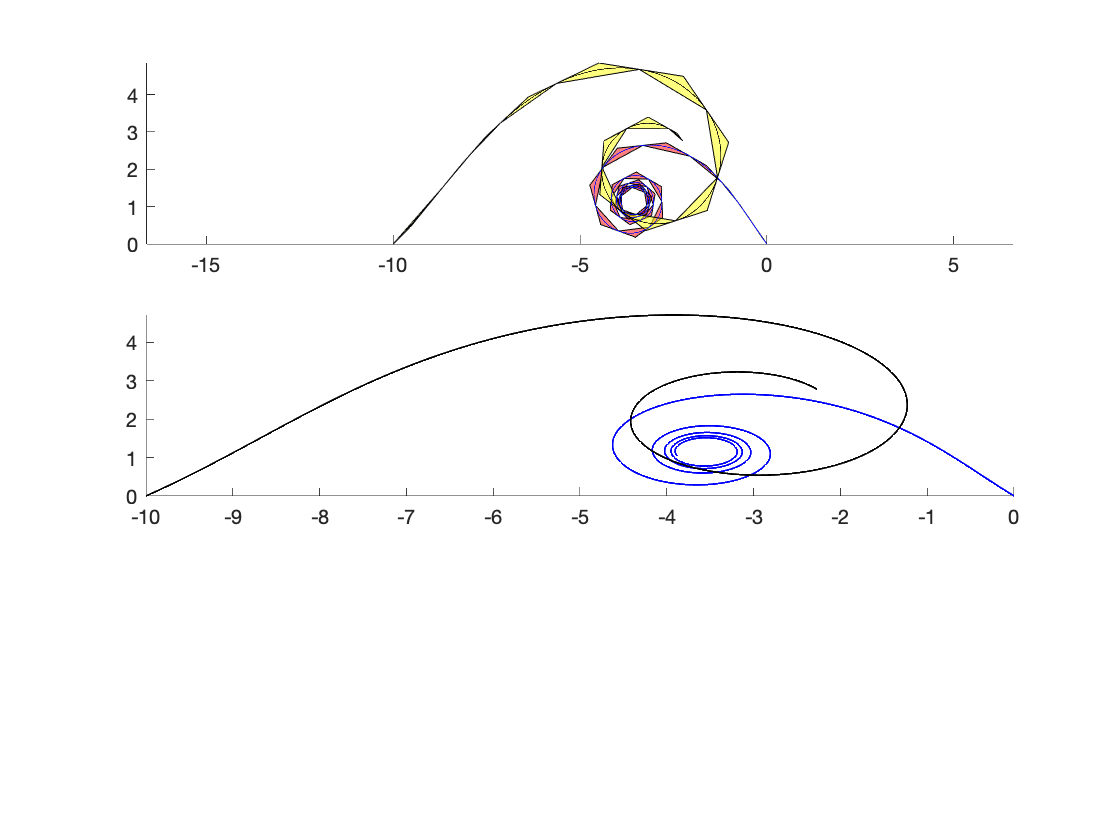


for i=1:size(P1,2)
  fill( [P1(1,i),P2(1,i),P3(1,i)], ...
        [P1(2,i),P2(2,i),P3(2,i)], ...
        'red','FaceAlpha',0.5 );
end

for i=1:size(Q1,2)
  fill( [Q1(1,i),Q2(1,i),Q3(1,i)], ...
        [Q1(2,i),Q2(2,i),Q3(2,i)], ...
        'yellow','FaceAlpha',0.5 );
end

plot( XY1(1,:), XY1(2,:), '-b', 'LineWidth', 0.1 );
plot( XY2(1,:), XY2(2,:), '-k', 'LineWidth', 0.1 );

%AXY1 = pointsOnClothoid( c1.x0, c1.y0, c1.theta0, c1.kappa, c1.dkappa, c1.L/2 );
%AXY2 = pointsOnClothoid( c2.x0, c2.y0, c2.theta0, c2.kappa, c2.dkappa, c2.L/2 );
%plot( AXY1(1,:), AXY1(2,:), 'ob', 'LineWidth', 0.1 );
%plot( AXY2(1,:), AXY2(2,:), 'ok', 'LineWidth', 0.1 );


axis equal;

subplot(3,1,2);
hold on;

plot( XY1(1,:), XY1(2,:), '-b', 'LineWidth', 1 );
plot( XY2(1,:), XY2(2,:), '-k', 'LineWidth', 1 );


for i=1:size(P1,2)
  p0 = P1(:,i);
  p1 = P2(:,i);
  p2 = P3(:,i);
  for j=1:size(Q1,2)
    q0 = Q1(:,j);
    q1 = Q2(:,j);
    q2 = Q3(:,j);
    ii = TriTriOverlap( p0, p1, p2, q0, q1, q2 ); 
    if ii ~= 0
      fill( [p0(1),p1(1),p2(1)], ...
            [p0(2),p1(2),p2(2)], ...
            'red','FaceAlpha',0.1 );
      fill( [q0(1),q1(1),q2(1)], ...
            [q0(2),q1(2),q2(2)], ...
            'yellow','FaceAlpha',0.1 );
    end
  end
end

Error using TriTriOverlap (line 25)
this function is mex only. Run CompileLib.m script to build


axis equal;

subplot(3,1,3);
hold on;

plot( XY1(1,:), XY1(2,:), '-b', 'LineWidth', 1 );
plot( XY2(1,:), XY2(2,:), '-k', 'LineWidth', 1 );

[s1,s2] = CLOT1.intersect(CLOT2);

XY1 = CLOT1.eval( s1 );
XY2 = CLOT2.eval( s2 );

plot( XY1(1,:), XY1(2,:), 'ob', 'LineWidth', 2 );
plot( XY2(1,:), XY2(2,:), 'ok', 'LineWidth', 2 );

%for offs=[-0.5,0,0.5]
%  TT = bbClothoid( x0, y0, theta0, kappa, dkappa, L, max_angle, max_size, offs );
  %for i=1:size(TT,2)
    %fill( TT(1:2:end,i), TT(2:2:end,i), 'red');
    %end
  %end
%plot( XY(1,:), XY(2,:), '-b', 'LineWidth', 2 );

axis equal;